% Shear zone height calculations, plotter
% Use eps = v/h
% eps = strain rate (1/s)
% v = plate rate (cm/yr) 
% h = shear zone thickness (km)

% Convert units, eps to 1/yr, plate rate to km/yr 
% Conversion factors
s2yr = 3.1536e7

s2yr = 31536000

ctok = 1e-5

ctok = 1.0000e-05


%% INPUT DATA %%

% Strain rates (one for PS, one for DC)
eps_PS = 2.56e-13 % 1/s

eps_PS = 2.5600e-13

eps_DC = 8.47e-10 % 1/s

eps_DC = 8.4700e-10


% Plate rate (Sanbagawa)
v = 24 % cm/yr (Koyama, Wallis 2024)

v = 24


% Convert 
eps_PS_km = eps_PS * s2yr

eps_PS_km = 8.0732e-06

eps_DC_km = eps_DC * s2yr

eps_DC_km = 0.0267


v_km = v * ctok

v_km = 2.4000e-04


% Get h for Sanbagawa

h_San_PS = v_km / eps_PS_km

h_San_PS = 29.7279

h_San_DC = v_km / eps_DC_km

h_San_DC = 0.0090


% Set array of values for shear zone thickness
h = linspace(0.001, 35, 100)

h =     0.0010    0.3545    0.7081    1.0616    1.4151    1.7686    2.1222    2.4757    2.8292    3.1827    3.5363    3.8898    4.2433    4.5968    4.9504    5.3039    5.6574    6.0109    6.3645    6.7180    7.0715    7.4250    7.7786    8.1321    8.4856    8.8391    9.1927    9.5462    9.8997   10.2532   10.6068   10.9603   11.3138   11.6673   12.0209   12.3744   12.7279   13.0814   13.4350   13.7885   14.1420   14.4955   14.8491   15.2026   15.5561   15.9096   16.2632   16.6167   16.9702   17.3237


eps = ( v_km ./ h )./ s2yr

eps = 1.0e-08 *

    0.7610    0.0021    0.0011    0.0007    0.0005    0.0004    0.0004    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


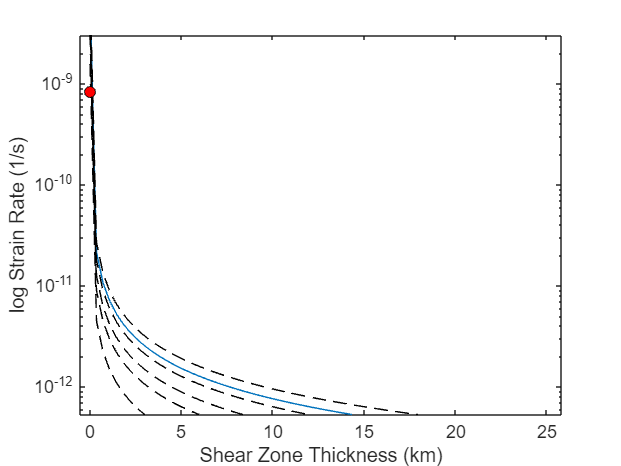


% Make values and lines for differing plate velocities

%% Velocity 
v_km_5 = 0.5e-4 ;%km/yr
v_km_10 = 1e-4 ;%km/yr
v_km_15 = 1.5e-4 ;%km/yr
v_km_20 = 2e-4 ;%km/yr
v_km_30 = 3e-4 ;%km/yr

eps_5 = ( v_km_5 ./ h )./ s2yr ;% Strain rate, 5 cm/yr
eps_10 = ( v_km_10 ./ h )./ s2yr ;% Strain rate, 5 cm/yr
eps_15 = ( v_km_14 ./ h )./ s2yr ;% Strain rate, 5 cm/yr
eps_20 = ( v_km_20 ./ h )./ s2yr ;% Strain rate, 5 cm/yr
eps_30 = ( v_km_30 ./ h )./ s2yr ;% Strain rate, 5 cm/yr
% Plot 
figure()
plot(h, eps)
hold on;
plot(h, eps_5, LineStyle = '--', color='k')
plot(h, eps_10,LineStyle = '--', color='k')
plot(h, eps_15,LineStyle = '--', color='k')
plot(h, eps_20,LineStyle = '--', color='k')
plot(h, eps_30,LineStyle = '--', color='k')

% Markers 
plot(h_San_PS, eps_PS, 'o', 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'k')
plot(h_San_DC, eps_DC, 'o', 'MarkerFaceColor', 'red', 'MarkerEdgeColor','k')

xlabel('Shear Zone Thickness (km)')
ylabel('log Strain Rate (1/s)')
%yline(eps_PS, LineStyle = '--')
%yline(eps_DC, LineStyle = '--')
set(gca, 'Yscale', 'log')
ylim([1e-14 1e-9])
hold off; 